root_path = 'D:\files\spectral_analysis\mat_demo\data\mix\';
% seed_varieties = ["zd958", "jd20", "nh816", "jh5"];   %% " "
% file_names = [25, 50, 75, 100, 125, 150];
% 
% ii = 1;
% jj = 6;
% 
% seed_variety = seed_varieties(ii);
% file_name = num2str(file_names(jj));

file_name = ["zda"];
hdr_path_name = strcat(root_path, file_name, '.hdr');
raw_path_name = strcat(root_path, file_name, '.raw');

% file path
% hdr_path_name = strcat(root_path, seed_variety, '\', file_name, '.hdr');
% raw_path_name = strcat(root_path, seed_variety, '\', file_name, '.raw');

% get dimensions and waves
info = get_info(hdr_path_name);
[samples, lines, bands, wavelengths] = get_dimensions(info);

% raman shift
raman_shift = 10^7/785 - 10^7./wavelengths;

% get datacube
rawdata = get_rawdata(raw_path_name);
rawcube0 = reshape(rawdata, [samples, bands, lines]);
rawcube = permute(rawcube0, [3, 1, 2]);

% effective raman shift 
[~, p1] = min(abs(raman_shift - 400));
[~, p2] = min(abs(raman_shift - 1800));
effshift = raman_shift(p1:p2);


% define effcube
effcube = rawcube(:, 385:875, p1:p2);
efflines = size(effcube, 1);
effsamples = size(effcube, 2);
effbands = size(effcube, 3);

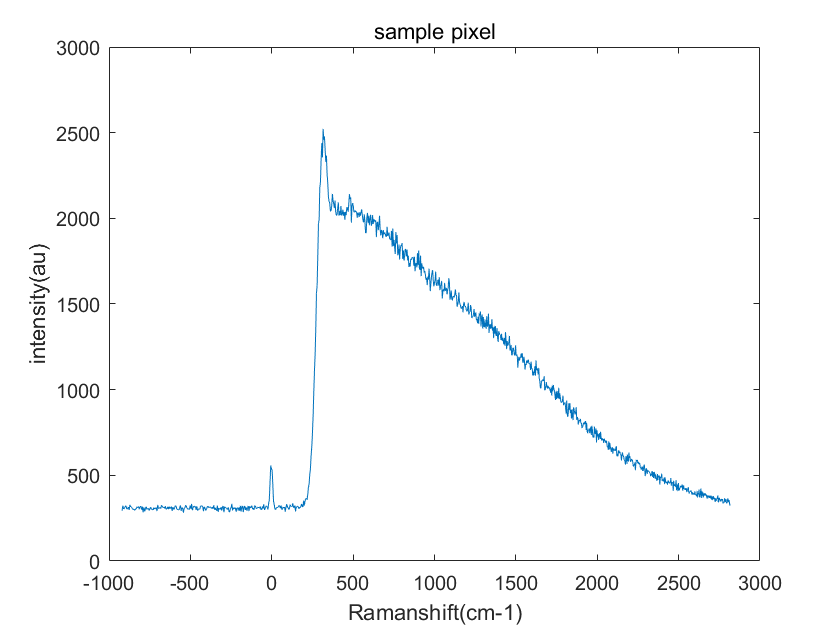

display_pixel(rawcube, raman_shift, 315, 610);

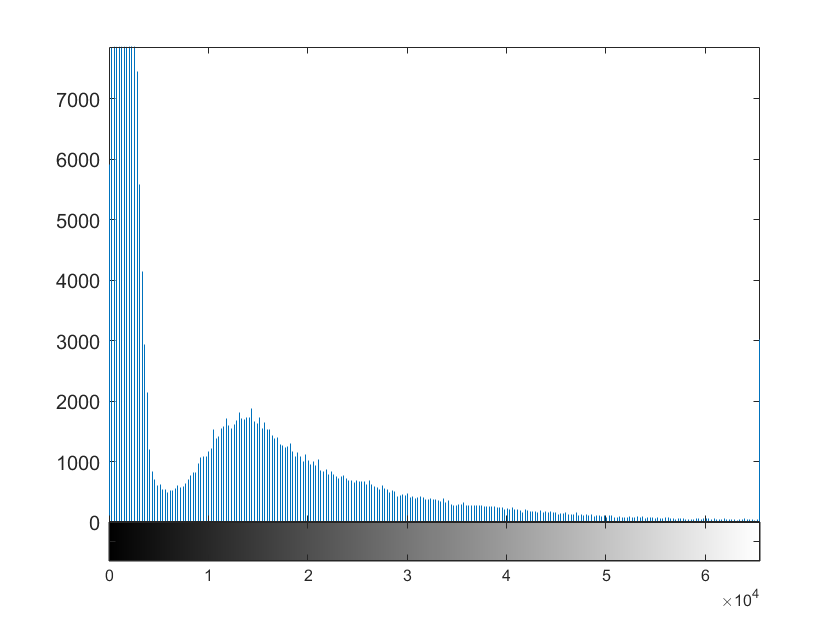

%% mask

% effective band for mask
[~, b] = min(abs(effshift - 477));

% mask 
img = imadjust(effcube(:, :, b));
figure; imhist(img); 

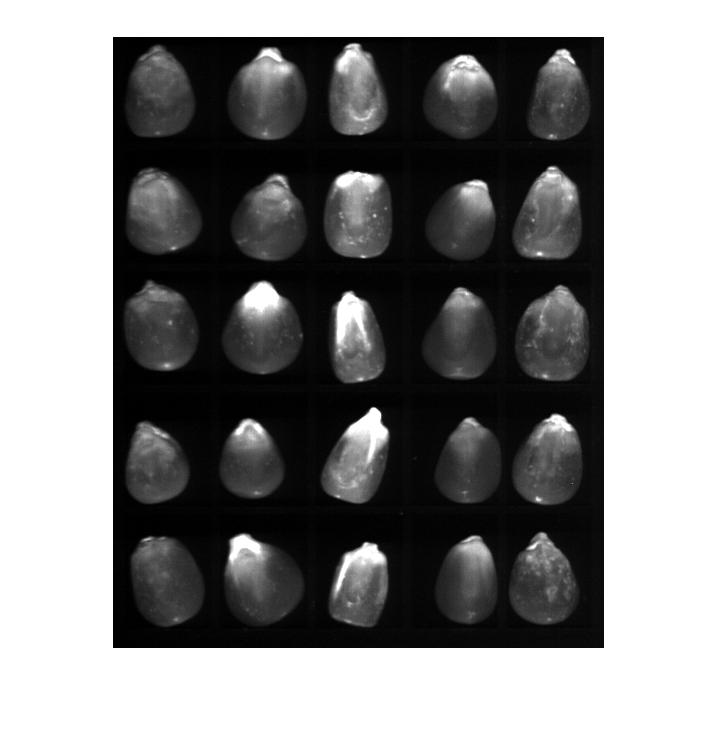

figure; imshow(img);

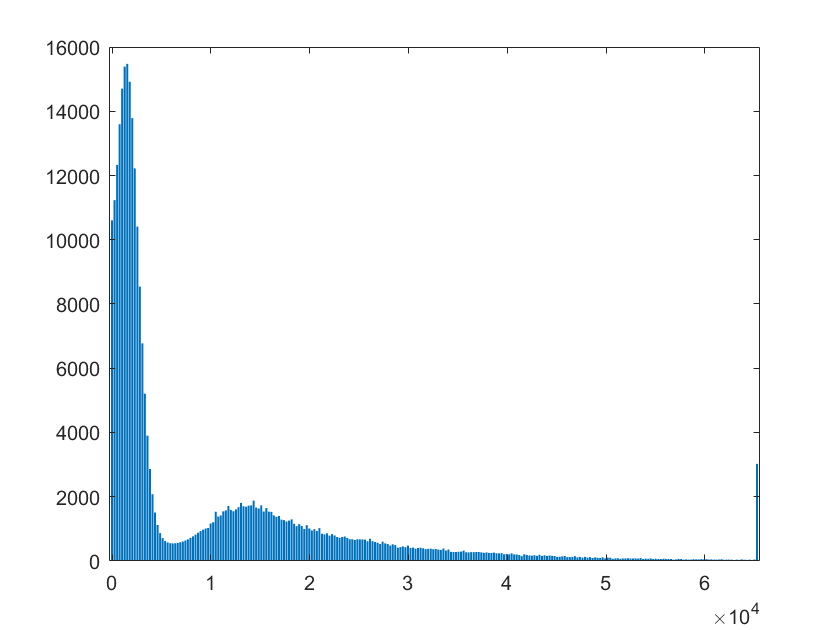


[bw, t, hist_smooth] = get_mask(effcube, b);

figure; bar([0:255]*256, hist_smooth);

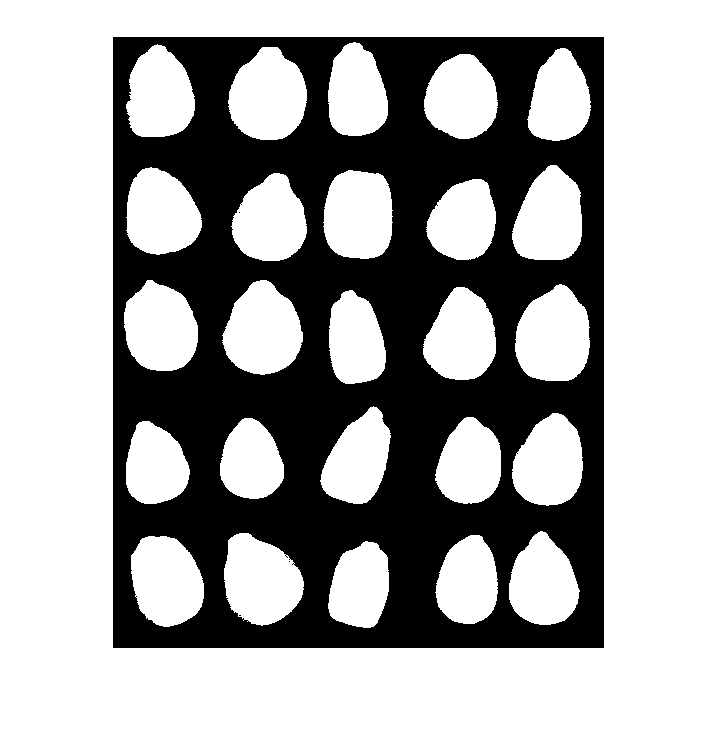

figure; imshow(bw);

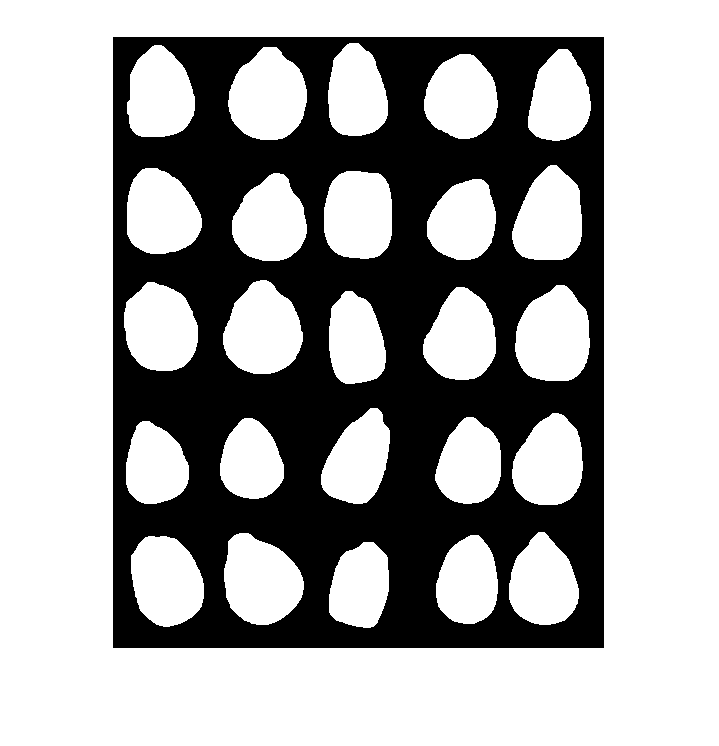

% morphology
se1 = strel('disk', 8);
se2 = strel('disk', 4);
bw_final = imopen(imclose(bw, se2), se1);
bw_final = bwareaopen(bw_final, 1000, 8);    
figure; imshow(bw_final); 

num =     25


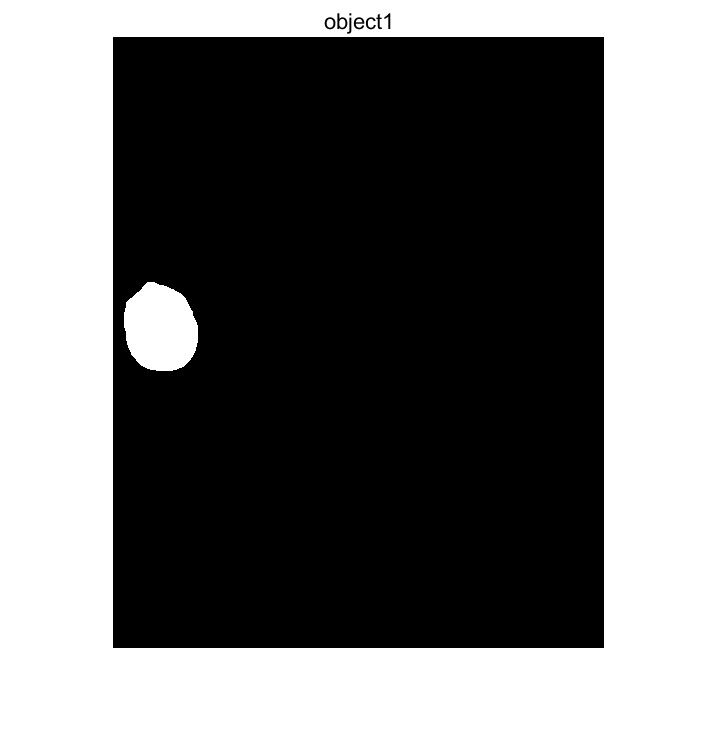

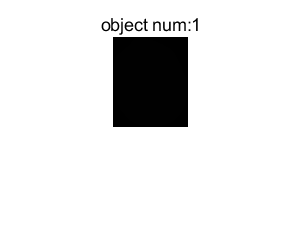

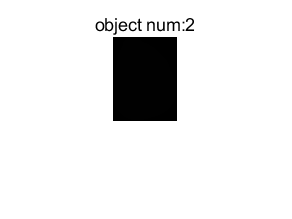

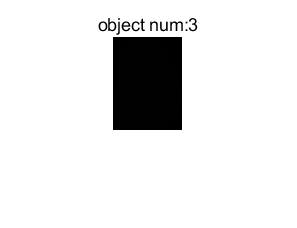

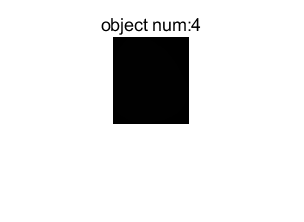

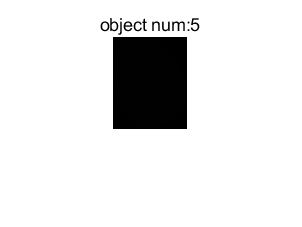

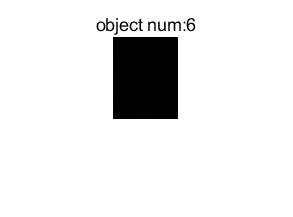

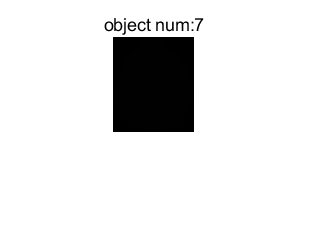

label = get_single_roi(bw_final);

rgbimg = imread('zd150.jpg')

rgbimg = 1796×1445×3 uint8 数组
rgbimg(:,:,1) =

   124   123   125   126   126   125   125   123   124   124   124   124   123   121   119   118   117   117   117   118   117   116   114   114   112   111   109   111   114   117   122   122   122   120   117   115   115   115   116   116   117   117   120   120   119   121   121   120   118   118   118   120   121   125   128   129   130   130   127   130   133   134   132   129   126   123   124   126   128   131   131   131   130   125   128   127   128   130   132   133   134   134   133   129   124   119   113   111   109   110   111   112   114   114   115   116   119   120   123   124   126   129   131   133   137   142   142   142   139   134   129   127   124   124   123   122   122   123   126   128   131   135   137   137   136   138   145   147   143   137   134   128   128   126   124   123   121   120   119   118   118   120   123   123   122   121   120   124   128   129   128   130   131   130   130   130   130   130   12

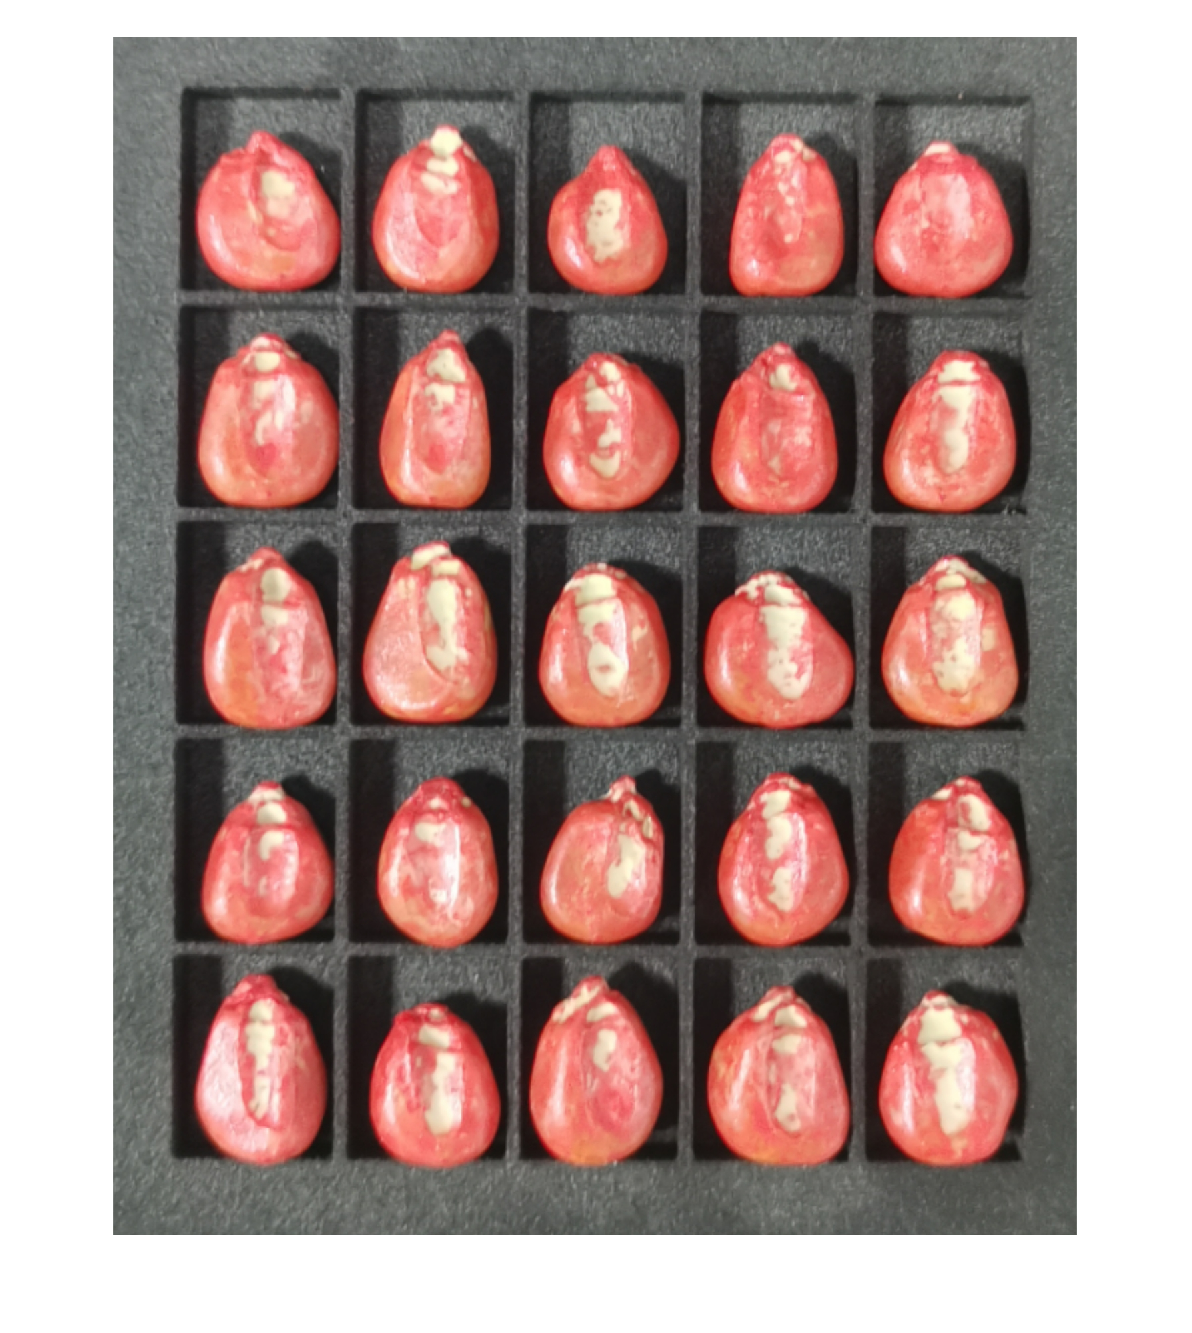

% figure('Units','normalized', 'Position', [0, 0, 1, 0.6]);
figure
% subplot(1,3,1);
imshow(rgbimg);

% xlabel('(a)', "FontSize", 25)
% set(gca,'fontsize',25, 'FontWeight','bold');
% subplot(1,3,2);
% imshow(img);
% % xlabel('(b)', "FontSize", 25)
% % set(gca,'fontsize',25, 'FontWeight','bold');
% subplot(1,3,3);
% imshow(bw_final);
% % xlabel('(c)', "FontSize", 25)
% % set(gca,'fontsize',25, 'FontWeight','bold');